# Thermodynamically constrain a metabolic model

## **Author: Ronan Fleming, Leiden University**

## **Reviewers: **

## INTRODUCTION

In flux balance analysis of genome scale stoichiometric models of metabolism, the principal constraints are uptake or secretion rates, the steady state mass conservation assumption and reaction directionality. Von Bertylanffy [1,4] is a set of methods for (i) quantitative estimation of thermochemical parameters for metabolites and reactions using the component contribution method [3], (ii) quantitative assignment of reaction directionality in a multi-compartmental genome scale model based on an application of the second law of thermodynamics to each reaction [2], (iii) analysis of thermochemical parameters in a network context, and (iv) thermodynamically constrained flux balance analysis. The theoretical basis for each of these methods is detailed within the cited papers.

## PROCEDURE

## Configure the environment

All the installation instructions are in a separate .md file named vonBertalanffy.md in docs/source/installation

With all dependencies installed correctly, we configure our environment, verfy all dependencies, and add required fields and directories to the matlab path.

initVonBertalanffy

ChemAxon Marvin Beans is installed and working.


aPath = which('initVonBertalanffy');
basePath = strrep(aPath,'vonBertalanffy/initVonBertalanffy.m','');
addpath(genpath(basePath))
folderPattern=[filesep 'new'];
method = 'remove';
editCobraToolboxPath(basePath,folderPattern,method)

removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/componentContribution/new
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/new
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/inchi/new
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/molFiles/new
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/protons/new


# Select the model

This tutorial is tested for the E. coli model iAF1260 and the human metabolic model Recon3Dmodel. However, only the data for the former is provided within the COBRA Toolbox as it is used for testing von Bertylanffy. However, the figures generated below are most suited to plotting results for Recon3D, so they may not be so useful for iAF1260.  The Recon3D example uses values from literature for input variables where they are available.

%modelName = 'iAF1260';
%modelName='Ec_iAF1260_flux1'; 
%modelName='Recon3DModel_301'; 
%modelName='Recon3DModel_Dec2017';
modelName='Recon3.0model';

## Load a model

Load a model, and save it as the original model in the workspace, unless it is already loaded into the workspace. 

clear model
global CBTDIR
modelFileName = [modelName '.mat']

modelFileName = 'Recon3.0model.mat'



switch modelName
    case 'Ec_iAF1260_flux1'
        modelDirectory = getDistributedModelFolder(modelFileName); %Look up the folder for the distributed Models.
        modelFileName= [modelDirectory filesep modelFileName]; % Get the full path. Necessary to be sure, that the right model is loaded
        
        modelFileName = [modelName '.xml']
        model = readCbModel(modelFileName);
        if model.S(952, 350)==0
            model.S(952, 350)=1; % One reaction needing mass balancing in iAF1260
        end
        model.metCharges(strcmp('asntrna[Cytosol]', model.mets))=0; % One reaction needing charge balancing
        
    case 'iAF1260'
        modelDirectory = getDistributedModelFolder(modelFileName); %Look up the folder for the distributed Models.
        modelFileName= [modelDirectory filesep modelFileName]; % Get the full path. Necessary to be sure, that the right model is loaded

        model = readCbModel(modelFileName);
        model.mets = cellfun(@(mets) strrep(mets,'_c','[c]'),model.mets,'UniformOutput',false);
        model.mets = cellfun(@(mets) strrep(mets,'_e','[e]'),model.mets,'UniformOutput',false);
        model.mets = cellfun(@(mets) strrep(mets,'_p','[p]'),model.mets,'UniformOutput',false);
        bool = strcmp(model.mets,'lipa[c]old[c]');
        model.mets{bool}='lipa_old_[c]';
        bool = strcmp(model.mets,'lipa[c]old[e]');
        model.mets{bool}='lipa_old_[e]';
        bool = strcmp(model.mets,'lipa[c]old[p]');
        model.mets{bool}='lipa_old_[p]';
        if model.S(952, 350)==0
            model.S(952, 350)=1; % One reaction needing mass balancing in iAF1260
        end
        model.metCharges(strcmp('asntrna[c]', model.mets))=0; % One reaction needing charge balancing
        
    case 'Recon3.0model'
        modelDirectory='~/work/sbgCloud/programReconstruction/projects/recon2models/data/reconXComparisonModels';
        model = loadIdentifiedModel(modelName,modelDirectory);
        model.csense(1:size(model.S,1),1)='E';
        %Hack for thermodynamics
        model.metFormulas{strcmp(model.mets,'h[i]')}='H';
        model.metFormulas(cellfun('isempty',model.metFormulas)) = {'R'};
        if isfield(model,'metCharge')
            model.metCharges = double(model.metCharge);
            model=rmfield(model,'metCharge');
        end
        modelOrig = model;
        
    case 'Recon3DModel_Dec2017'
        modelDirectory = getDistributedModelFolder(modelFileName); %Look up the folder for the distributed Models.
        modelFileName= [modelDirectory filesep modelFileName]; % Get the full path. Necessary to be sure, that the right model is loaded

        model = readCbModel(modelFileName);
        model.csense(1:size(model.S,1),1)='E';
        %Hack for thermodynamics
        model.metFormulas{strcmp(model.mets,'h[i]')}='H';
        model.metFormulas(cellfun('isempty',model.metFormulas)) = {'R'};
        if isfield(model,'metCharge')
            model.metCharges = double(model.metCharge);
            model=rmfield(model,'metCharge');
        end
        modelOrig = model;
    case 'Recon3DModel_301'
        modelDirectory = getDistributedModelFolder(modelFileName); %Look up the folder for the distributed Models.
        modelFileName= [modelDirectory filesep modelFileName]; % Get the full path. Necessary to be sure, that the right model is loaded

        model = readCbModel(modelFileName);
        %Hack for thermodynamics
        model.metFormulas(cellfun('isempty',model.metFormulas)) = {'R'};
        modelOrig = model;
    otherwise
            error('setup specific parameters for your model')
end

## Set the directory containing the results

switch modelName
    case 'Ec_iAF1260_flux1'
        resultsPath=which('tutorial_vonBertalanffy.mlx');
        resultsPath=strrep(resultsPath,'/tutorial_vonBertalanffy.mlx','');
        resultsPath=[resultsPath filesep modelName '_results'];
        resultsBaseFileName=[resultsPath filesep modelName '_results'];
    case 'iAF1260'
        resultsPath=which('tutorial_vonBertalanffy.mlx');
        resultsPath=strrep(resultsPath,'/tutorial_vonBertalanffy.mlx','');
        resultsPath=[resultsPath filesep modelName '_results'];
        resultsBaseFileName=[resultsPath filesep modelName '_results'];
    case 'Recon3.0model'
        basePath='~/work/sbgCloud';
        resultsPath=[basePath '/programReconstruction/projects/recon2models/results/thermo/new2_' modelName];
        resultsBaseFileName=[resultsPath filesep modelName '_' datestr(now,30) '_'];
     case 'Recon3DModel_Dec2017'
        basePath='~/work/sbgCloud';
        resultsPath=[basePath '/programReconstruction/projects/recon2models/results/thermo/' modelName];
        resultsBaseFileName=[resultsPath filesep modelName '_' datestr(now,30) '_'];
    case 'Recon3DModel_301'
        basePath='~/work/sbgCloud';
        resultsPath=which('tutorial_vonBertalanffy.mlx');
        resultsPath=strrep(resultsPath,'/tutorial_vonBertalanffy.mlx','');
        resultsPath=[resultsPath filesep modelName '_results'];
        resultsBaseFileName=[resultsPath filesep modelName '_results'];
    otherwise
        error('setup specific parameters for your model')
end

## Set the directory containing molfiles

switch modelName
    case 'Ec_iAF1260_flux1'
        molfileDir = 'iAF1260Molfiles';
    case 'iAF1260'
        molfileDir = 'iAF1260Molfiles';
    case 'Recon3DModel_Dec2017'
        molfileDir = [basePath '/data/metDatabase/explicit/molFiles'];
        %molfileDir = [basePath '/programModelling/projects/atomMapping/results/molFilesDatabases/DBimplicitHMol'];
        %molfileDir = [basePath '/programModelling/projects/atomMapping/results/molFilesDatabases/DBexplicitHMol'];
    case {'Recon3DModel_301','Recon3.0model'}
        molfileDir = [basePath '/data/metDatabase/explicit/molFiles']; 
        molfileDir = [basePath '/code/fork-ctf/mets/molFiles'];
    otherwise
        error('setup specific parameters for your model')
end

## Set the thermochemical parameters for the model

switch modelName
    case 'Ec_iAF1260_flux1'
        T = 310.15; % Temperature in Kelvin
        compartments = {'Cytosol'; 'Extra_organism'; 'Periplasm'}; % Cell compartment identifiers
        ph = [7.7; 7.7; 7.7]; % Compartment specific pH
        is = [0.25; 0.25; 0.25]; % Compartment specific ionic strength in mol/L
        chi = [0; 90; 90]; % Compartment specific electrical potential relative to cytosol in mV        
    case 'iAF1260'
        T = 310.15; % Temperature in Kelvin
        compartments = ['c'; 'e'; 'p']; % Cell compartment identifiers
        ph = [7.7; 7.7; 7.7]; % Compartment specific pH
        is = [0.25; 0.25; 0.25]; % Compartment specific ionic strength in mol/L
        chi = [0; 90; 90]; % Compartment specific electrical potential relative to cytosol in mV
    case 'Recon3DModel_Dec2017'
        % Temperature in Kelvin
        T = 310.15; 
        % Cell compartment identifiers
        compartments = ['c'; 'e'; 'g'; 'l'; 'm'; 'n'; 'r'; 'x';'i']; 
        % Compartment specific pH
        ph = [7.2; 7.4; 6.35; 5.5; 8; 7.2; 7.2; 7; 7.2]; 
        % Compartment specific ionic strength in mol/L
        is = 0.15*ones(length(compartments),1); 
        % Compartment specific electrical potential relative to cytosol in mV
        chi = [0; 30; 0; 19; -155; 0; 0; -2.303*8.3144621e-3*T*(ph(compartments == 'x') - ph(compartments == 'c'))/(96485.3365e-6); 0]; 
    case {'Recon3DModel_301','Recon3.0model'}
        % Temperature in Kelvin
        T = 310.15; 
        % Cell compartment identifiers
        compartments = ['c'; 'e'; 'g'; 'l'; 'm'; 'n'; 'r'; 'x';'i']; 
        % Compartment specific pH
        ph = [7.2; 7.4; 6.35; 5.5; 8; 7.2; 7.2; 7; 7.2]; 
        % Compartment specific ionic strength in mol/L
        is = 0.15*ones(length(compartments),1); 
        % Compartment specific electrical potential relative to cytosol in mV
        chi = [0; 30; 0; 19; -155; 0; 0; -2.303*8.3144621e-3*T*(ph(compartments == 'x') - ph(compartments == 'c'))/(96485.3365e-6); 0]; 
    otherwise
        error('setup specific parameters for your model')
end

## Set the default range of metabolite concentrations

switch modelName
    case 'Ec_iAF1260_flux1'
        concMinDefault = 1e-5; % Lower bounds on metabolite concentrations in mol/L
        concMaxDefault = 0.02; % Upper bounds on metabolite concentrations in mol/L
        metBoundsFile=[];
    case 'iAF1260'
        concMinDefault = 1e-5; % Lower bounds on metabolite concentrations in mol/L
        concMaxDefault = 0.02; % Upper bounds on metabolite concentrations in mol/L
        metBoundsFile=[];
    case 'Recon3DModel_Dec2017'
        concMinDefault=1e-5; % Lower bounds on metabolite concentrations in mol/L
        concMaxDefault=1e-2; % Upper bounds on metabolite concentrations in mol/L
        metBoundsFile=which('HumanCofactorConcentrations.txt');%already in the COBRA toolbox
    case {'Recon3DModel_301','Recon3.0model'}
        concMinDefault=1e-5; % Lower bounds on metabolite concentrations in mol/L
        concMaxDefault=1e-2; % Upper bounds on metabolite concentrations in mol/L
        metBoundsFile=which('HumanCofactorConcentrations.txt');%already in the COBRA toolbox
    otherwise
        error('setup specific parameters for your model')
end

## Set the desired confidence level for estimation of thermochemical parameters

The confidence level for estimated standard transformed reaction Gibbs energies is used to quantitatively assign reaction directionality.

switch modelName
    case 'Ec_iAF1260_flux1'
        confidenceLevel = 0.95; 
        DrGt0_Uncertainty_Cutoff = 20; %KJ/KMol    
    case 'iAF1260'
        confidenceLevel = 0.95; 
        DrGt0_Uncertainty_Cutoff = 20; %KJ/KMol
    case {'Recon3DModel_301','Recon3.0model'}
        confidenceLevel = 0.95;
        DrGt0_Uncertainty_Cutoff = 20; %KJ/KMol
    otherwise
        confidenceLevel = 0.95;
        DrGt0_Uncertainty_Cutoff = 20; %KJ/KMol
end

## Prepare folder for results

if ~exist(resultsPath,'dir')
    mkdir(resultsPath)
end
cd(resultsPath)

## Set the print level and decide to record a diary or not (helpful for debugging)

printLevel=2;

diary([resultsPath filesep 'diary.txt'])

# Setup a thermodynamically constrained model

## Read in the metabolite bounds

setDefaultConc=1;
setDefaultFlux=0;
rxnBoundsFile=[];
model=readMetRxnBoundsFiles(model,setDefaultConc,setDefaultFlux,concMinDefault,concMaxDefault,metBoundsFile,rxnBoundsFile,printLevel);

Reading metabolite conc bounds from: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/experimentalData/metaboliteConcentrations/HumanCofactorConcentrations.txt
              adp[c]	     1e-07	    0.0019
              adp[m]	    0.0026	    0.0094
              amp[c]	     1e-07	    0.0012
              atp[c]	   0.00129	    0.0049
              atp[m]	    0.0028	    0.0204
              coa[c]	  2.92e-05	 0.0001168
              coa[m]	    0.0022	    0.0039
              na1[c]	     1e-07	     0.025
              na1[e]	    0.1326	    0.1554
              nad[c]	0.00010546	 0.0007572
              nad[m]	    0.0005	    0.0075
             nadh[c]	9.2574e-07	0.00038294
             nadh[m]	     1e-07	    0.0011
             nadp[c]	     1e-07	5.8284e-06
             nadp[m]	     1e-07	    0.0015
            nadph[c]	     1e-07	0.00037523
            nadph[m]	     1e-07	    0.0042
              nh4[c]	    0.0007	    0.0009
               pi[c]	     0.001	    0.0063


## Check inputs

model = configureSetupThermoModelInputs(model,T,compartments,ph,is,chi,concMinDefault,concMaxDefault,confidenceLevel);


Field metCompartments is missing from model structure. Attempting to create it.
Attempt to create field metCompartments successful.



## Check elemental balancing of metabolic reactions

ignoreBalancingOfSpecifiedInternalReactions=1;
if ~exist('massImbalance','var')
    if isfield(model,'Srecon')
        model.S=model.Srecon;
    end
    % Check for imbalanced reactions
    fprintf('\nChecking mass and charge balance.\n');
    %Heuristically identify exchange reactions and metabolites exclusively involved in exchange reactions
    if ~isfield(model,'SIntMetBool')  ||  ~isfield(model,'SIntRxnBool') || ignoreBalancingOfSpecifiedInternalReactions
        %finds the reactions in the model which export/import from the model
        %boundary i.e. mass unbalanced reactions
        %e.g. Exchange reactions
        %     Demand reactions
        %     Sink reactions
        model = findSExRxnInd(model,[],printLevel);
    end
    
    if ignoreBalancingOfSpecifiedInternalReactions
        [nMet,nRxn]=size(model.S);
        ignoreBalancingMetBool=false(nMet,1);
        for m=1:nMet
%             if strcmp(model.mets{m},'Rtotal3coa[m]')
%                 pause(0.1);
%             end
            if ~isempty(model.metFormulas{m})
                ignoreBalancingMetBool(m,1)=numAtomsOfElementInFormula(model.metFormulas{m},'FULLR');
            end
        end
        ignoreBalancingRxnBool=getCorrespondingCols(model.S,ignoreBalancingMetBool,model.SIntRxnBool,'inclusive');
        SIntRxnBool=model.SIntRxnBool;
        model.SIntRxnBool=model.SIntRxnBool & ~ignoreBalancingRxnBool;
    end
    
    printLevelcheckMassChargeBalance=-1;  % -1; % print problem reactions to a file
    %mass and charge balance can be checked by looking at formulas
    [massImbalance,imBalancedMass,imBalancedCharge,imBalancedRxnBool,Elements,missingFormulaeBool,balancedMetBool]...
        = checkMassChargeBalance(model,printLevelcheckMassChargeBalance,resultsBaseFileName);
    model.balancedRxnBool=~imBalancedRxnBool;
    model.balancedMetBool=balancedMetBool;
    model.Elements=Elements;
    model.missingFormulaeBool=missingFormulaeBool;
    
    %reset original boolean vector
    if ignoreBalancingOfSpecifiedInternalReactions
        model.SIntRxnBool=SIntRxnBool;
    end
end


Checking mass and charge balance.


Found multiple possible biomass reactions: biomass_reaction
Found multiple possible biomass reactions: biomass_maintenance
Found multiple possible biomass reactions: biomass_maintenance_noTrTr
ATP demand reaction is not considered an exchange reaction by default. It should be mass balanced:
DM_atp_c_	h2o[c] + atp[c] 	->	h[c] + adp[c] + pi[c] 


There are mass imbalanced reactions, see ~/work/sbgCloud/programReconstruction/projects/recon2models/results/thermo/new2_Recon3.0model/Recon3.0model_20210401T142517_mass_imbalanced_reactions.txt
There are mass balanced, but charge imbalanced reactions, see ~/work/sbgCloud/programReconstruction/projects/recon2models/results/thermo/new2_Recon3.0model/Recon3.0model_20210401T142517_charge_imbalanced_reactions.txt


## Check that the input data necessary for the component contribution method is in place

save('modelNew_prior_to_setupComponentContribution','model')
model = setupComponentContribution(model,molfileDir);

Creating MetStructures.sdf from molfiles.
Percentage of metabolites without mol files: 9.1%
Converting SDF to InChI strings.
Estimating metabolite pKa values.
     1

10fthf
     2

10fthf5glu
     3

10fthf6glu
     4

10fthf7glu
     5

11docrtsl
     6

11docrtstrn
     7

12HPET
     8

12harachd
     9

12htacr
    10

12ppd_R
    11

12ppd_S
    12

1331tacr
    13

13_cis_oretn
    14

13_cis_retn
    15

13_cis_retnglc
    16

13dampp
    17

13dmt
    18

13dpg
    19

14hmdz
    20

1513tacr
    21

1531tacr
    22

15HPET
    23

15dmt
    24

15kprostgf2
    25

17ahprgnlone
    26

17ahprgstrn
    27

18harachd
    28

1a2425thvitd2
    29

1a25dhvitd2
    30

1a25dhvitd3
    31

1hibup_S
    32

1hibupglu_S
    33

1hmdgluc
    34

1mncam
    35

1ohmdz
    36

1p3h5c
    37

1pipdn2c
    38

1pyr5c
    39

20ahchsterol
    40

21hprgnlone
    41

23cump
    42

23dh1i56dio
    43

23doguln
    44

23dpg
    45

2425dhvitd2
    46

2425dhvitd3
    47

24nph
    48

25aics

save('modelNew_after_setupComponentContribution','model')

## Prepare the training data for the component contribution method

training_data = prepareTrainingData(model,printLevel);

Successfully added 3914 values from TECRDB
Successfully added 223 formation energies
Successfully added 13 redox potentials
Loading the InChIs for the training data from: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/componentContribution/cache/kegg_inchies.mat
Successfully created balanced training-data structure: 672 compounds and 4138 reactions
Loading the pKa values for the training data from: cache/kegg_pkas.mat
1.	2hydog
2.	fum
3.	mescon
4.	retinal
5.	retinal_11_cis
6.	retinal_cis_13
7.	retinal_cis_9
Mapping model metabolites to nist compounds
Creating group incidence matrix
python2 /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/old/inchi2gv.py -s -i "InChI=1/C9H14N3O8P/c10-5-1-2-12(9(15)11-5)8-7(14)6(13)4(20-8)3-19-21(16,17)18/h1-2,4,6-8,13-14H,3H2,(H2,10,11,15)(H2,16,17,18)/p-2/t4-,6-,7-,8-/m1/s1/fC9H12N3O8P/h10,16H/q-2/b10-5+": Signal

save('training_dataNew_after_prepareTrainingData','training_data')

## Call the component contribution method

if ~isfield(model,'DfG0')
    [model,~] = componentContribution(model,training_data);
end

Running Component Contribution method


## Setup a thermodynamically constrained model

if ~isfield(model,'DfGt0')
    model = setupThermoModel(model,confidenceLevel);
end


Estimating standard transformed Gibbs energies of formation.

Estimating bounds on transformed Gibbs energies.
Additional effect due to possible change in chemical potential of Hydrogen ions for transport reactions.
Additional effect due to possible change in electrical potential for transport reactions.


## Generate a model with reactants instead of major microspecies

if ~isfield(model,'Srecon') 
    printLevel_pHbalanceProtons=-1;

    model=pHbalanceProtons(model,massImbalance,printLevel_pHbalanceProtons,resultsBaseFileName);
end

## Determine quantitative directionality assignments

if ~exist('directions','var')
    fprintf('Quantitatively assigning reaction directionality.\n');
    [modelThermo, directions] = thermoConstrainFluxBounds(model,confidenceLevel,DrGt0_Uncertainty_Cutoff,printLevel);
end

Quantitatively assigning reaction directionality.


9/10600 reactions with DrGtMin=DrGtMax~=0
4/10600 reactions with DrGtMin=DrGtMax=0
The following reactions have DrGtMax=DrGtMin=0:
H2Oter	h2o[c] 	<=>	h2o[r] 
H2Otn	h2o[n] 	<=>	h2o[c] 
Htr	h[c] 	<=>	h[r] 
HMR_1095	h[c] 	<=>	h[n] 
ACYP


## Analyse thermodynamically constrained model

Choose the cutoff for probablity that reaction is reversible

cumNormProbCutoff=0.2;

Build Boolean vectors with reaction directionality statistics

[modelThermo,directions]=directionalityStats(modelThermo,directions,cumNormProbCutoff,printLevel);

9/10600 reactions with DrGtMin=DrGtMax~=0
4/10600 reactions with DrGtMin=DrGtMax=0
Qualitative internal reaction directionality:
      8791	 internal reconstruction reaction directions.
      5208	 forward reconstruction assignment.
         4	 reverse reconstruction assignment.
      3579	 reversible reconstruction assignment.

Quantitative internal reaction directionality:
      8791	 internal reconstruction reaction directions.
      7155	 of which have a thermodynamic assignment.
      1632	 of which have no thermodynamic assignment.
       871	 forward thermodynamic only assignment.
       325	 reverse thermodynamic only assignment.
      5959	 reversible thermodynamic only assignment.

Qualitiative vs Quantitative:
      2992	 Reversible -> Reversible
       159	 Reversible -> Forward
       185	 Reversible -> Reverse
       239	 Reversible -> Uncertain
       712	 Forward -> Forward
       140	 Forward -> Reverse
      2965	 Forward -> Reversible
      1391	 Forward -> Uncertain

% directions    a structue of boolean vectors with different directionality
%               assignments where some vectors contain subsets of others
%
% qualtiative -> quantiative changed reaction directions
%   .forward2Forward
%   .forward2Reverse
%   .forward2Reversible
%   .forward2Uncertain
%   .reversible2Forward
%   .reversible2Reverse
%   .reversible2Reversible
%   .reversible2Uncertain
%   .reverse2Forward
%   .reverse2Reverse
%   .reverse2Reversible
%   .reverse2Uncertain
%   .tightened
%
% subsets of qualtiatively forward  -> quantiatively reversible 
%   .forward2Reversible_bydGt0
%   .forward2Reversible_bydGt0LHS
%   .forward2Reversible_bydGt0Mid
%   .forward2Reversible_bydGt0RHS
% 
%   .forward2Reversible_byConc_zero_fixed_DrG0
%   .forward2Reversible_byConc_negative_fixed_DrG0
%   .forward2Reversible_byConc_positive_fixed_DrG0
%   .forward2Reversible_byConc_negative_uncertain_DrG0
%   .forward2Reversible_byConc_positive_uncertain_DrG0

Write out reports on directionality changes for individual reactions to the results folder.

fprintf('%s\n','directionalityChangeReport...');

directionalityChangeReport...


directionalityChangeReport(modelThermo,directions,cumNormProbCutoff,printLevel,resultsBaseFileName)

Generate pie charts with proportions of reaction directionalities and changes in directionality

fprintf('%s\n','directionalityStatFigures...');

directionalityStatFigures...


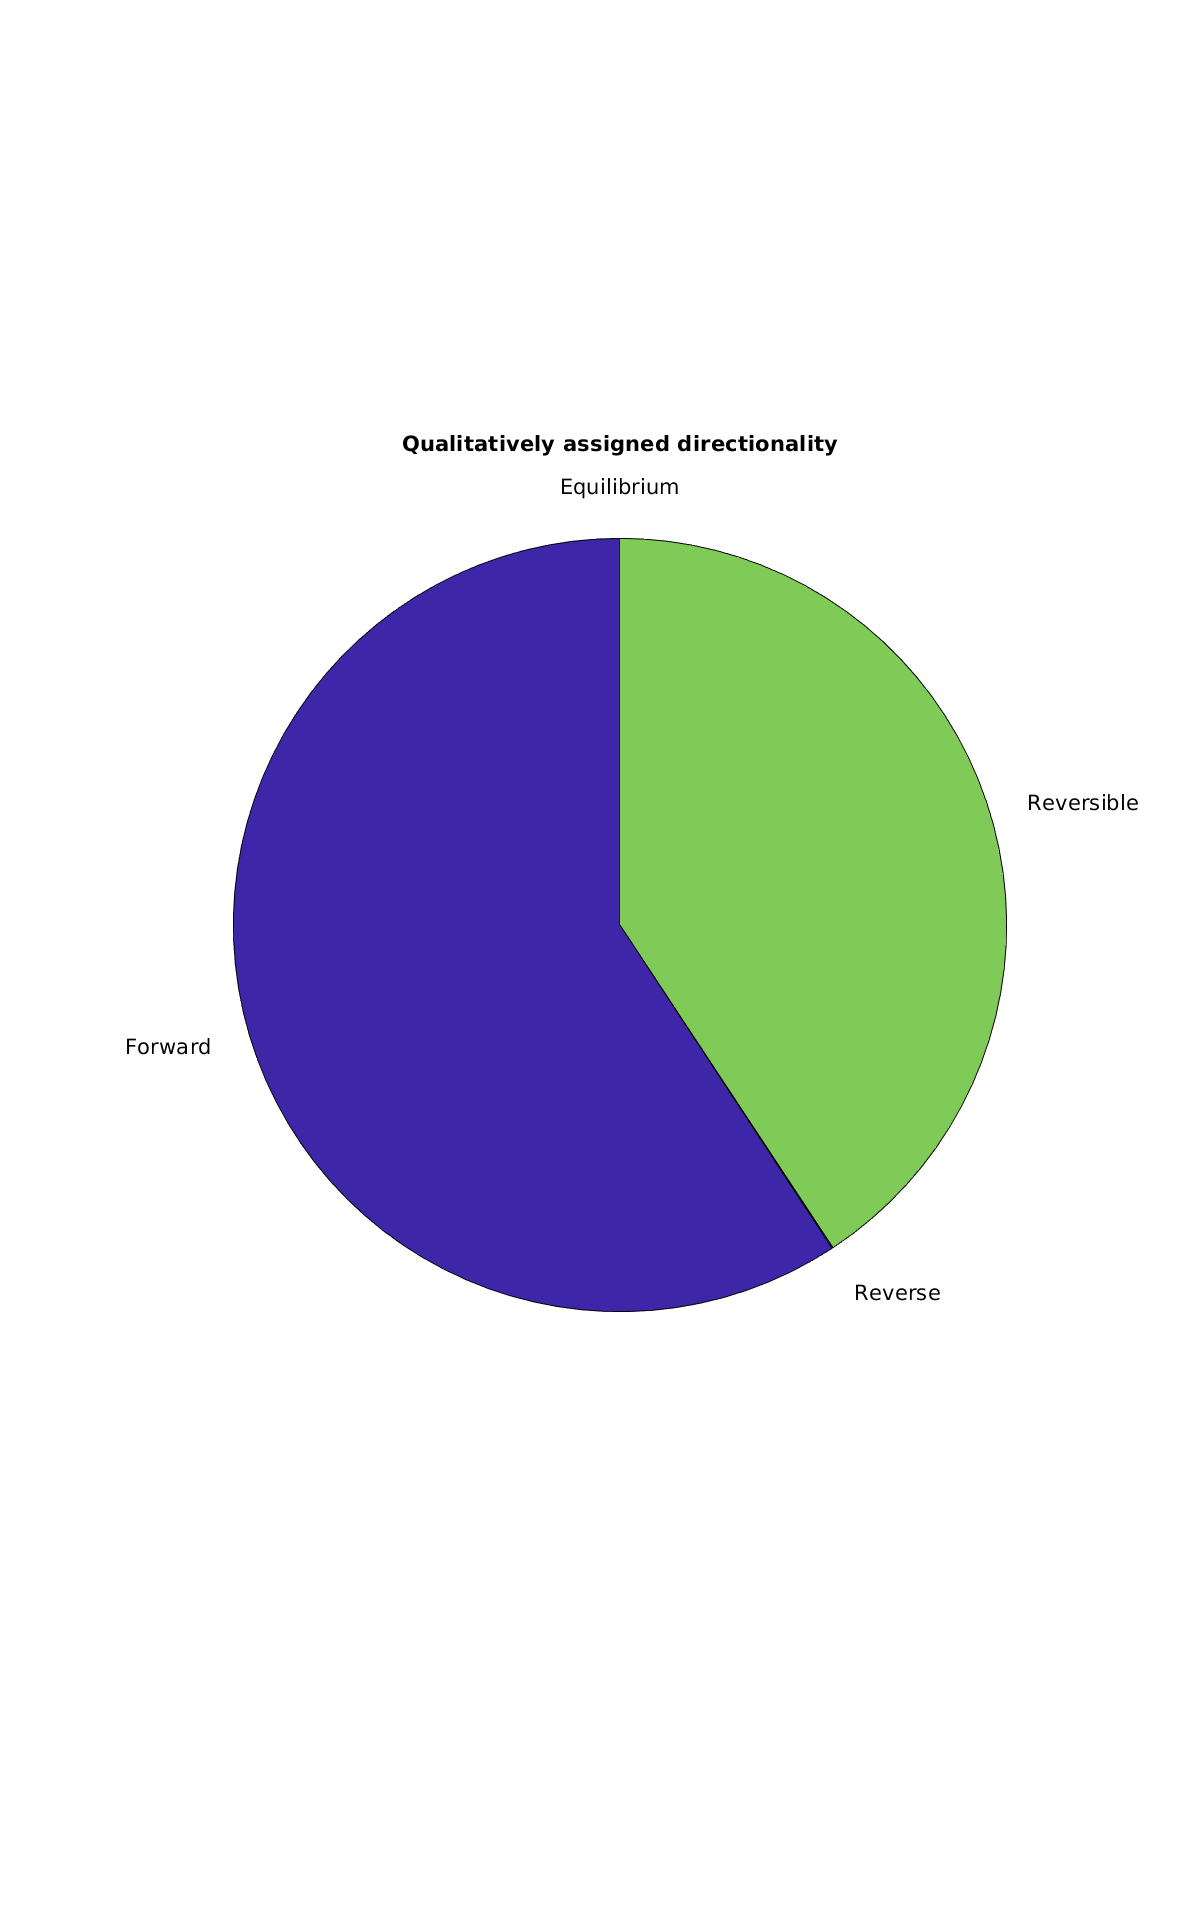

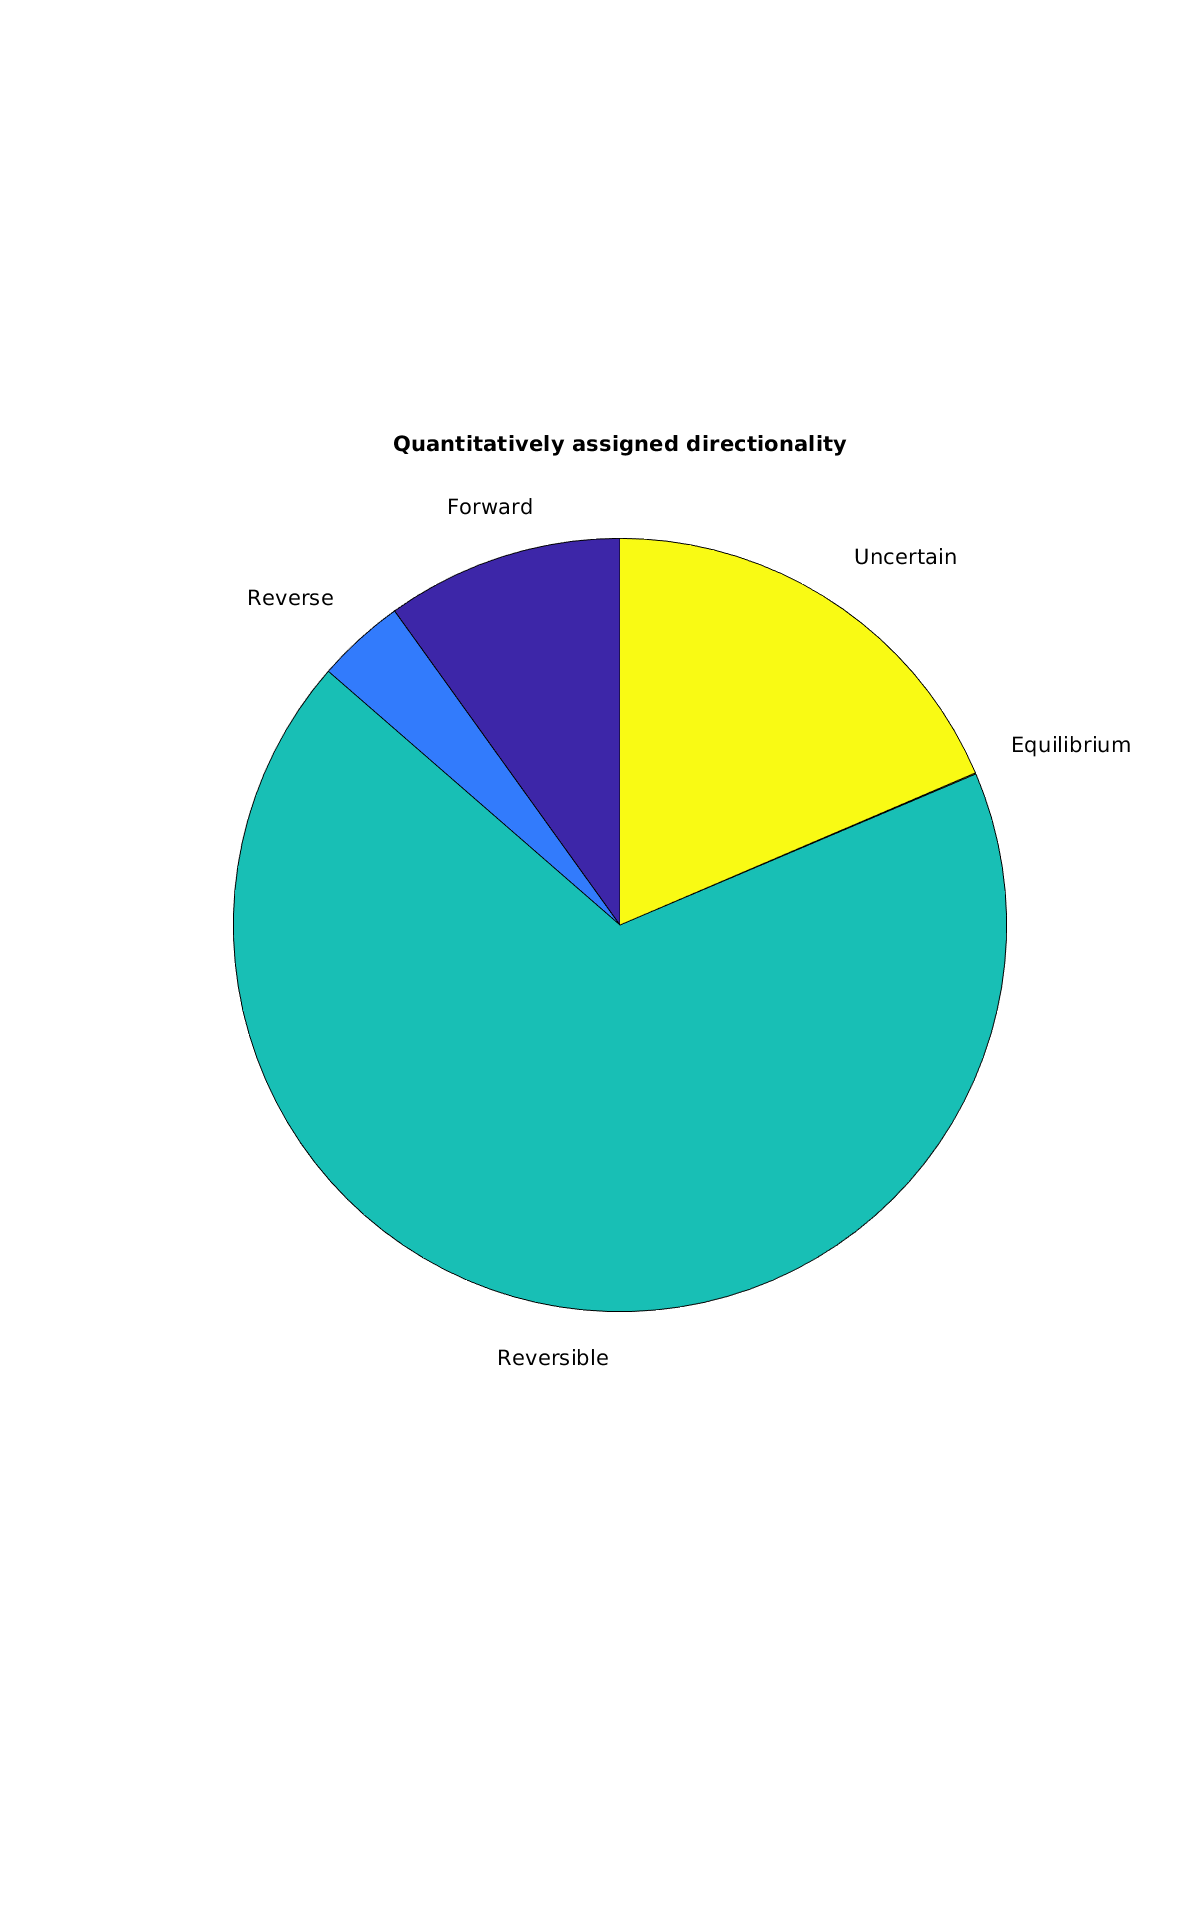

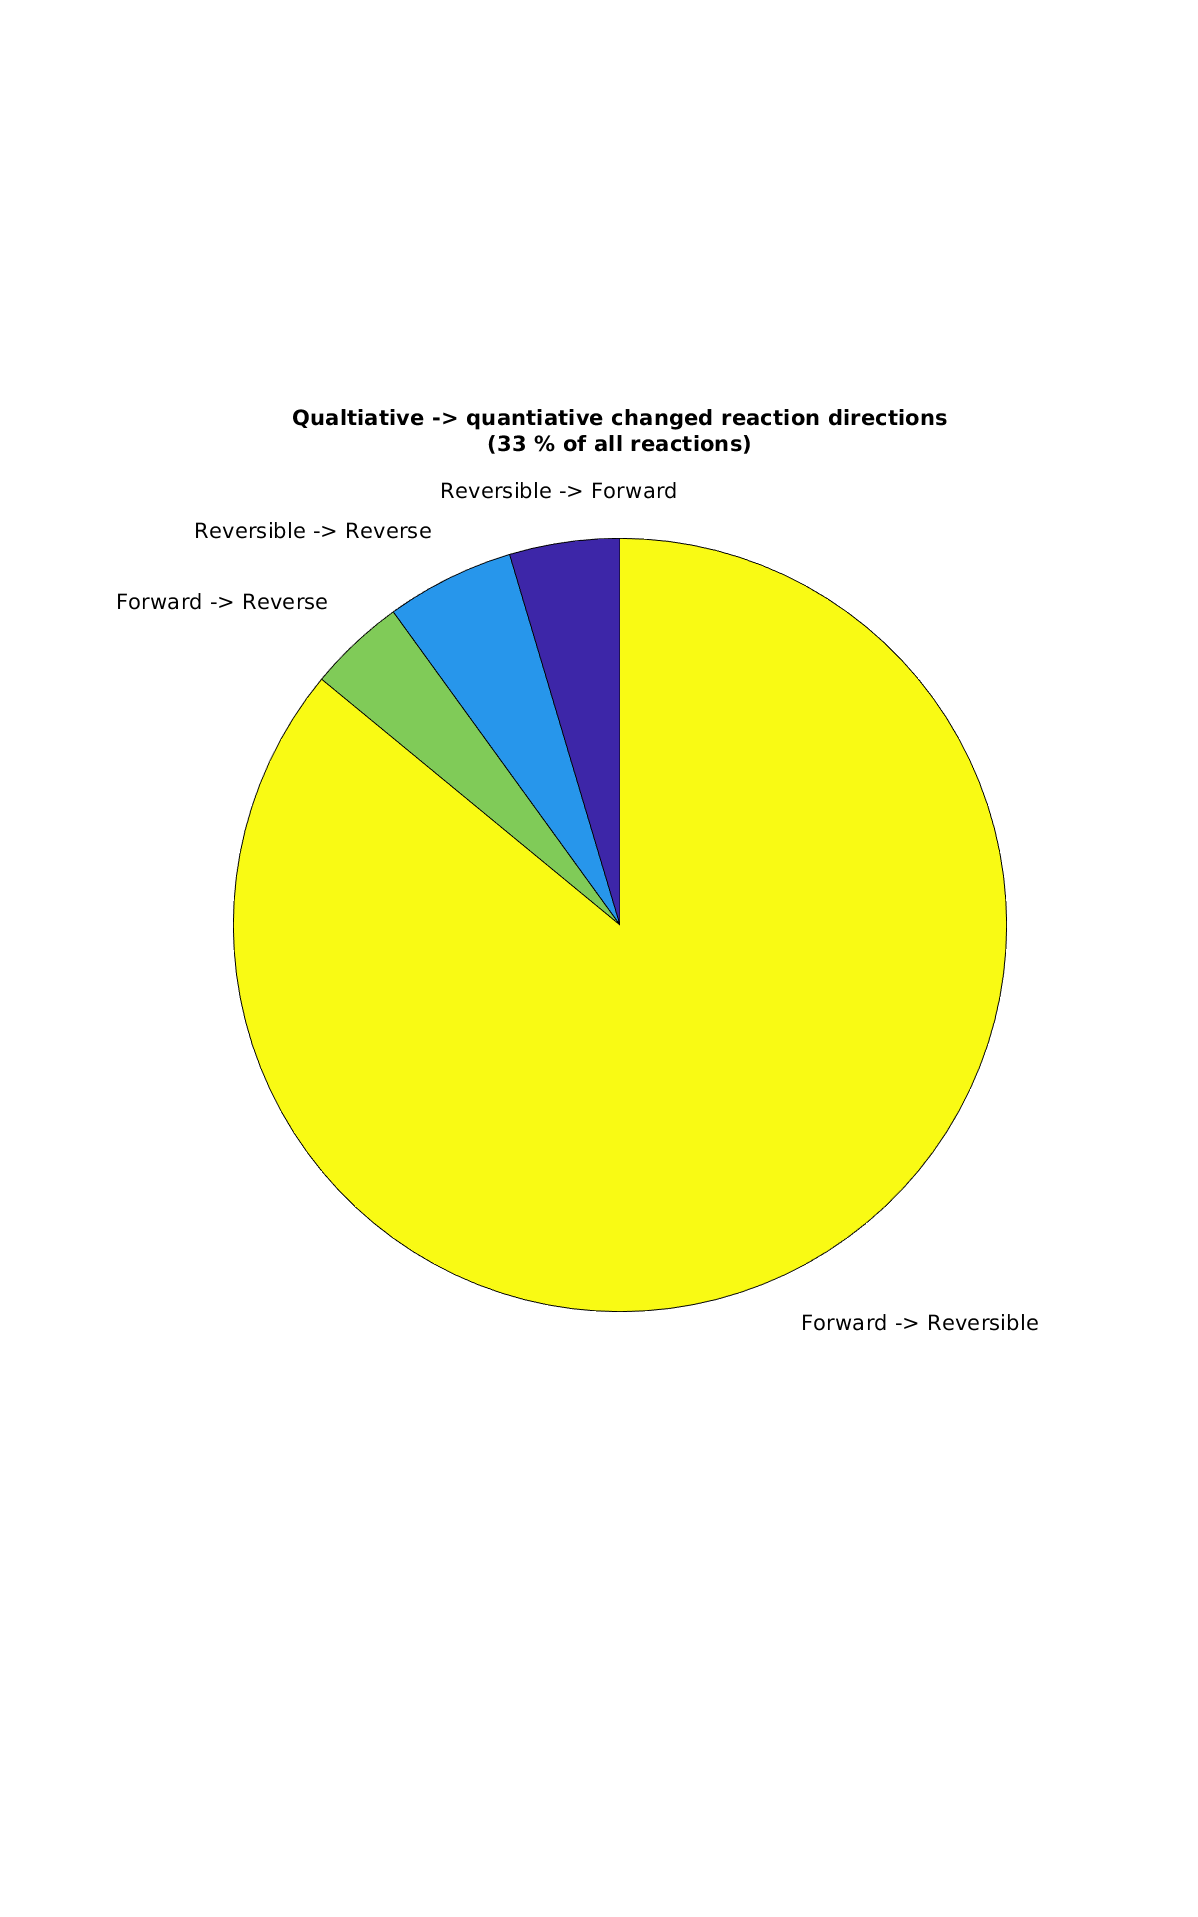

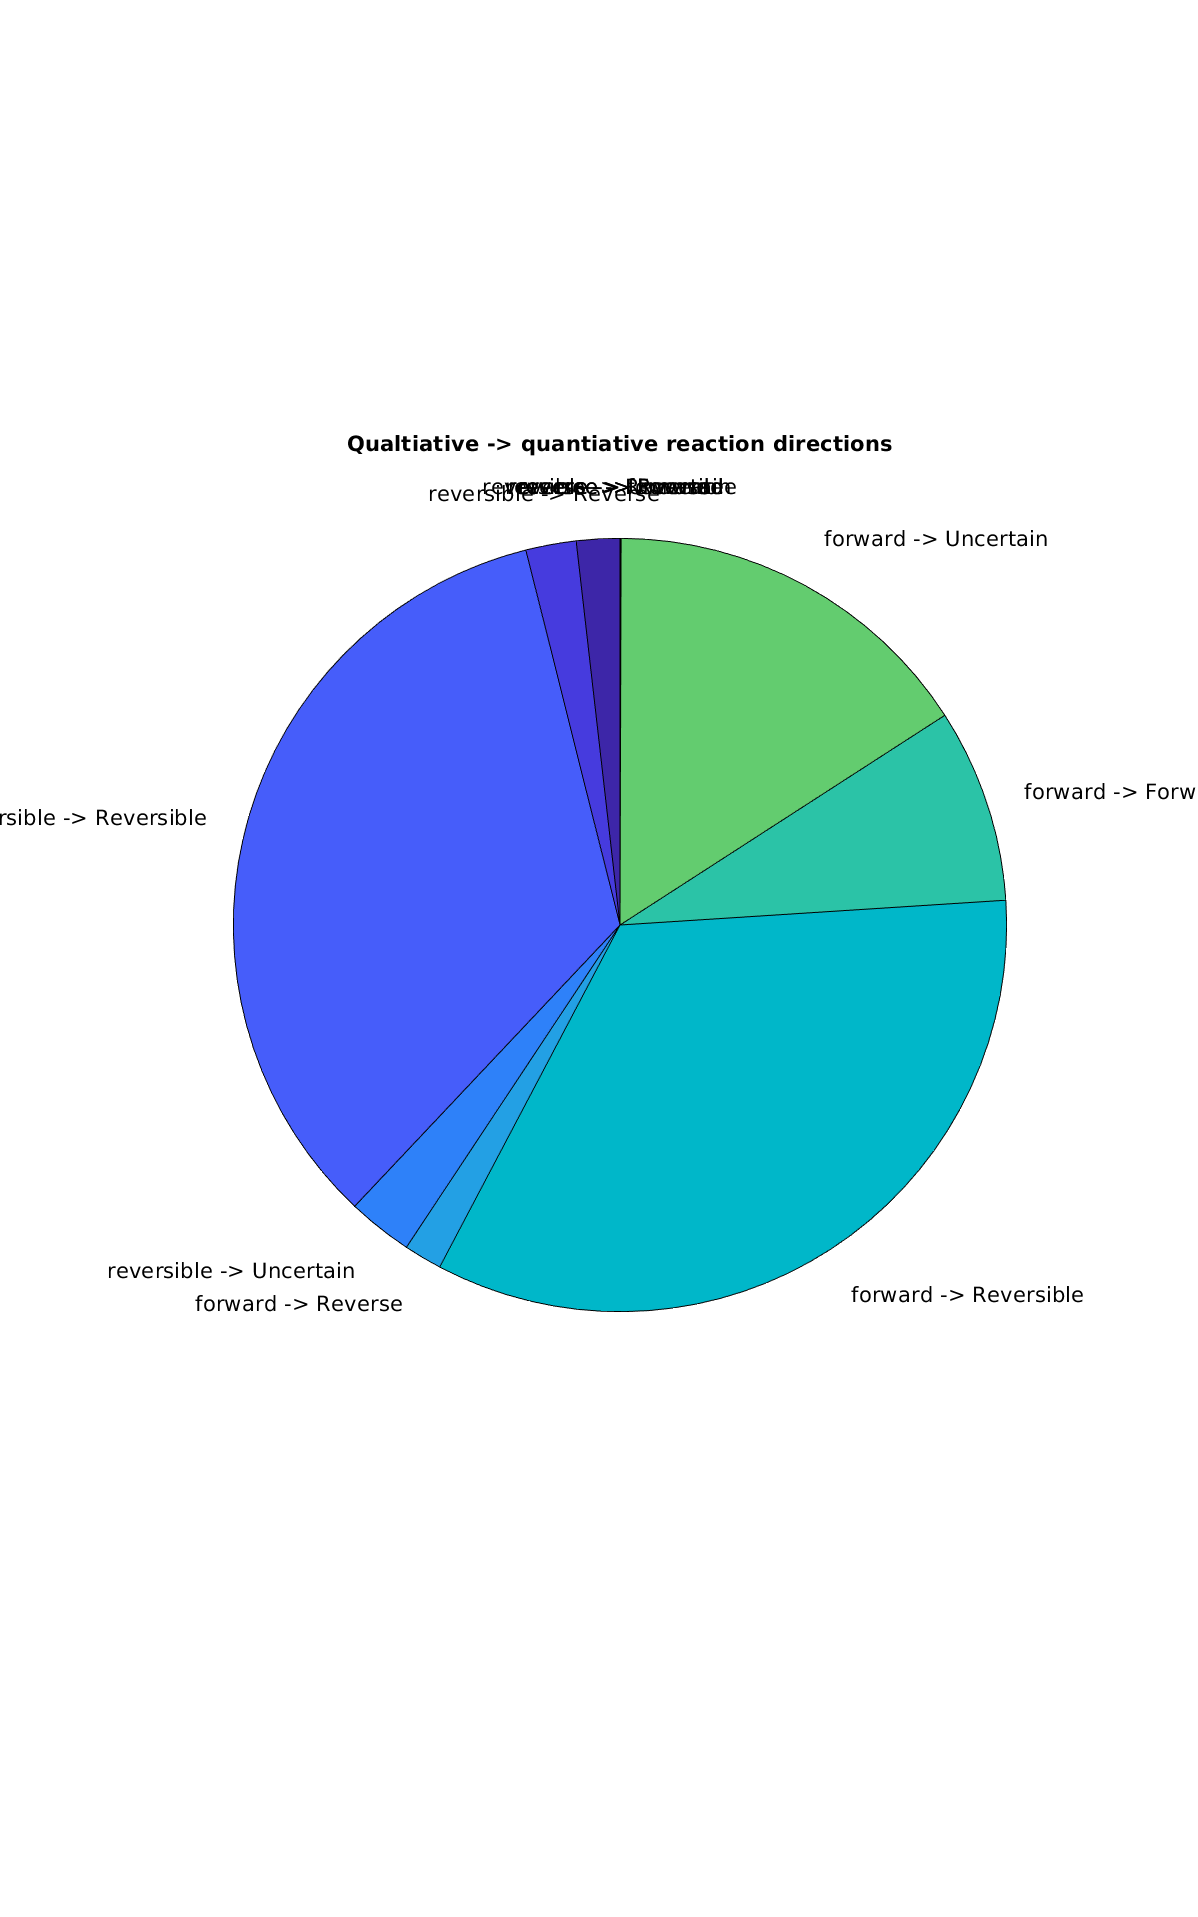

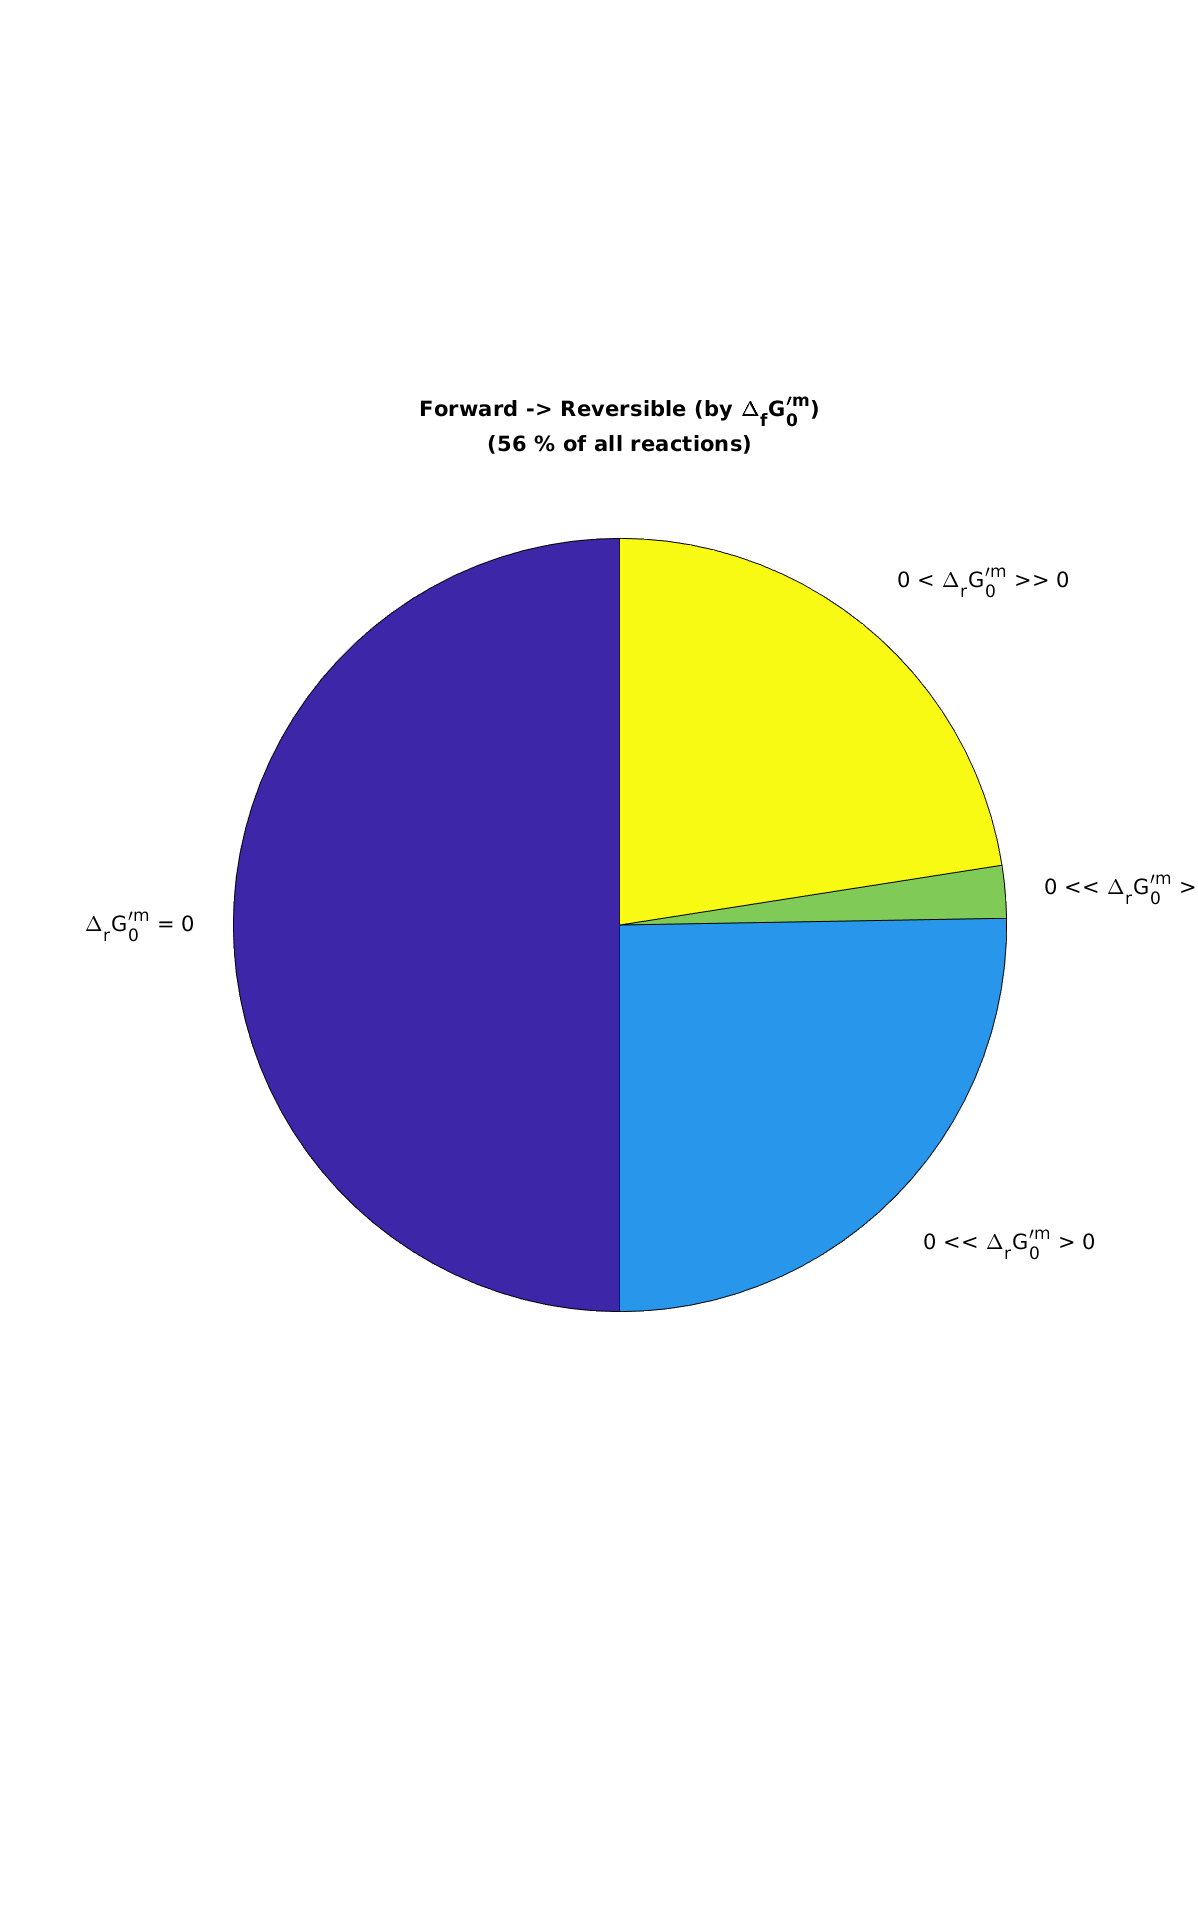

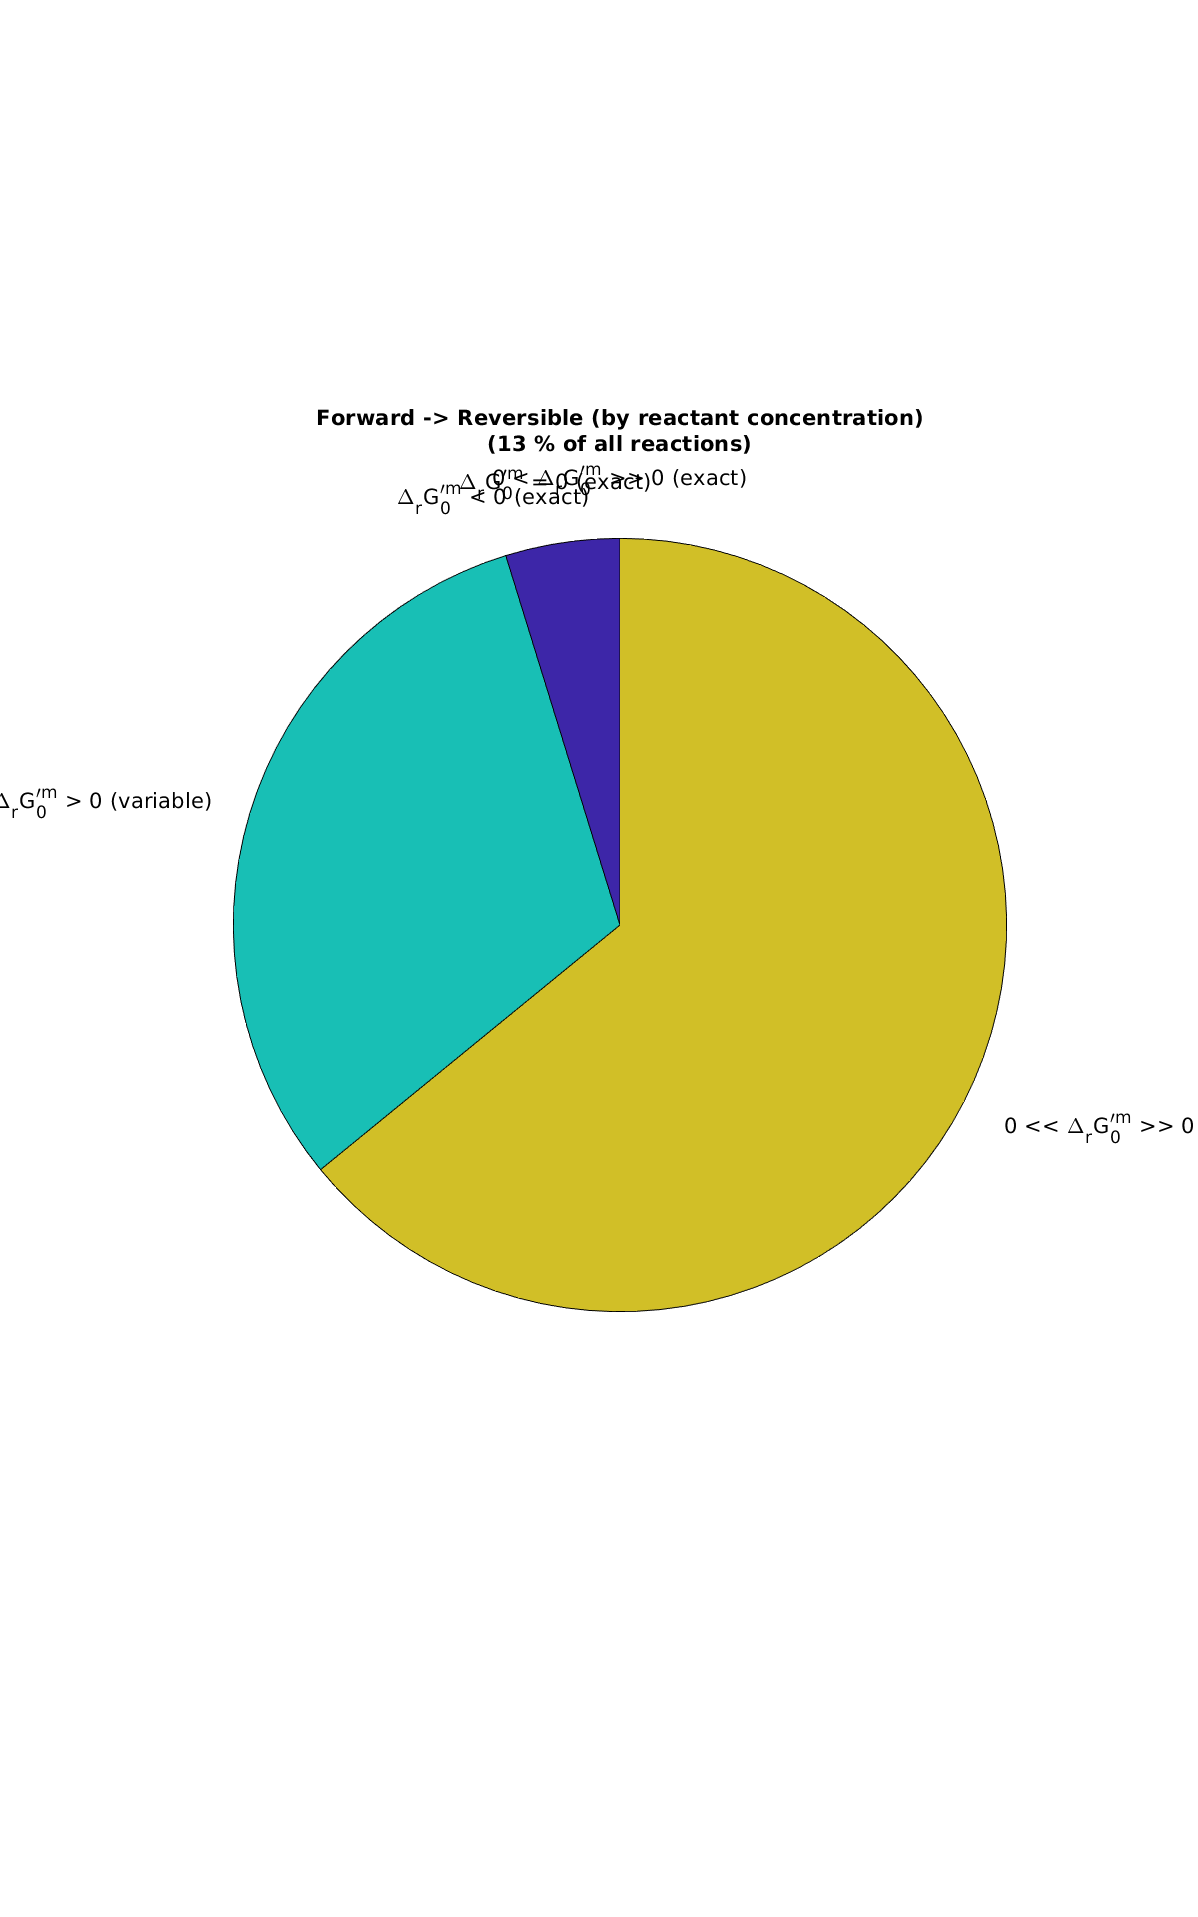

directionalityStatsFigures(directions,resultsBaseFileName)

Generate figures to interpret the overall reasons for reaction directionality changes for the qualitatively forward now quantiatiavely reversible reactions

forwardReversibleFigures...


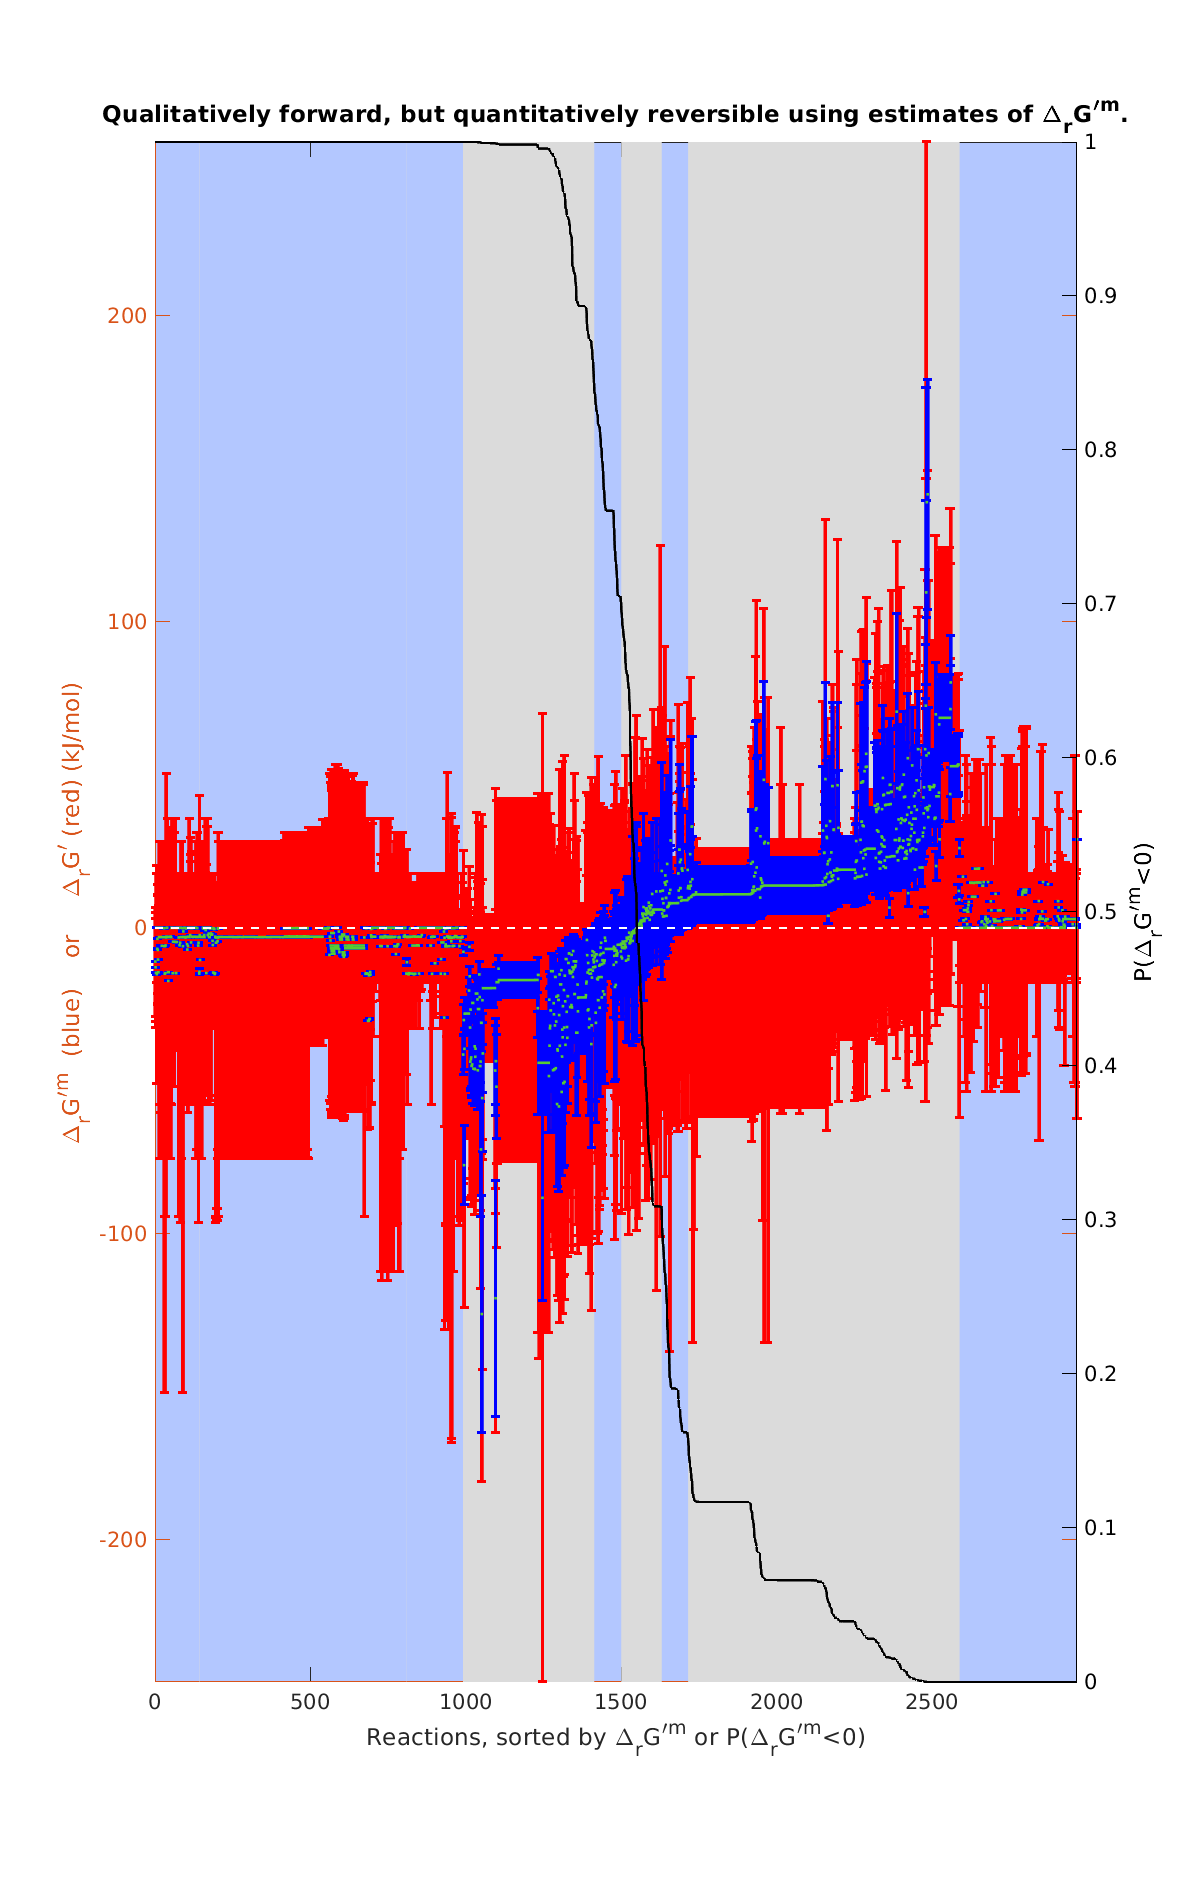

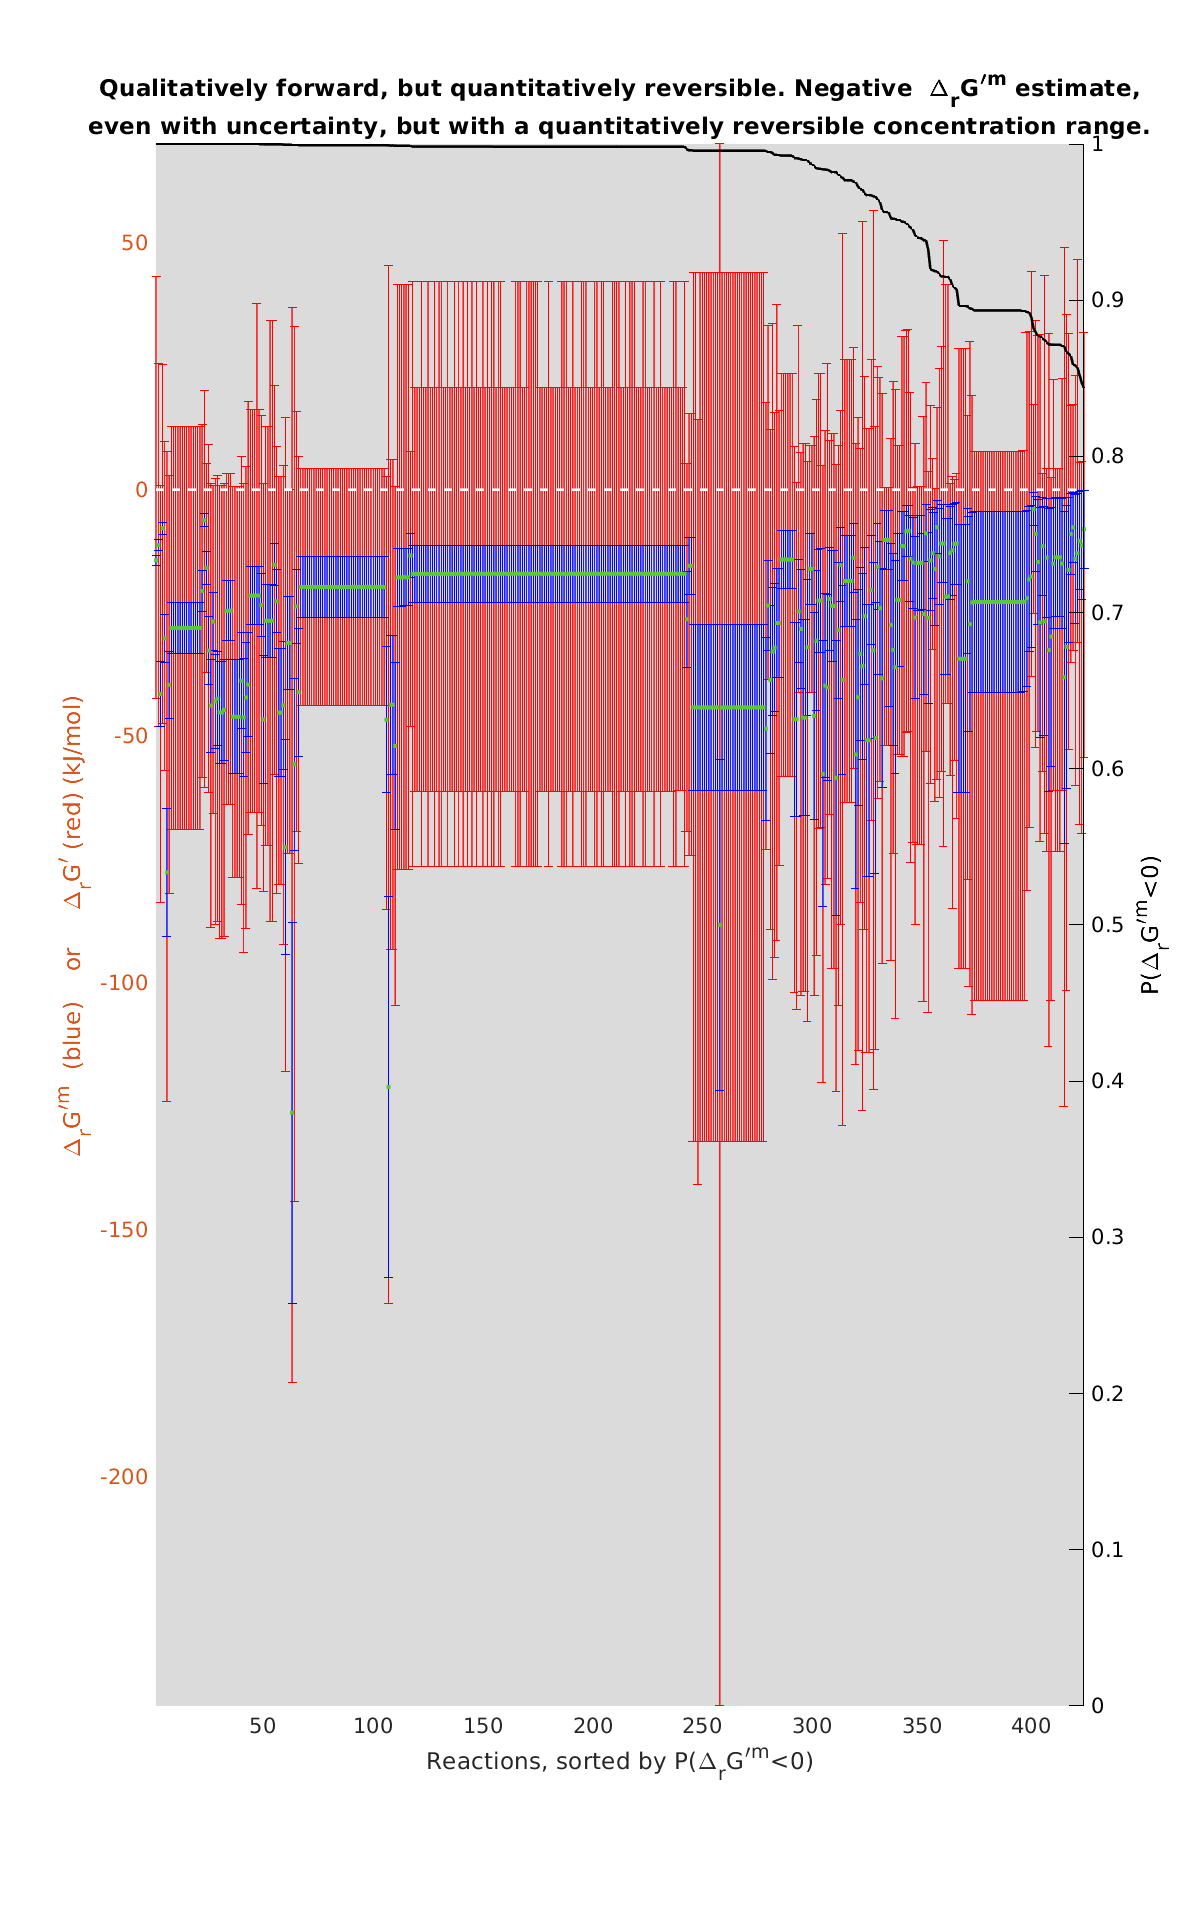

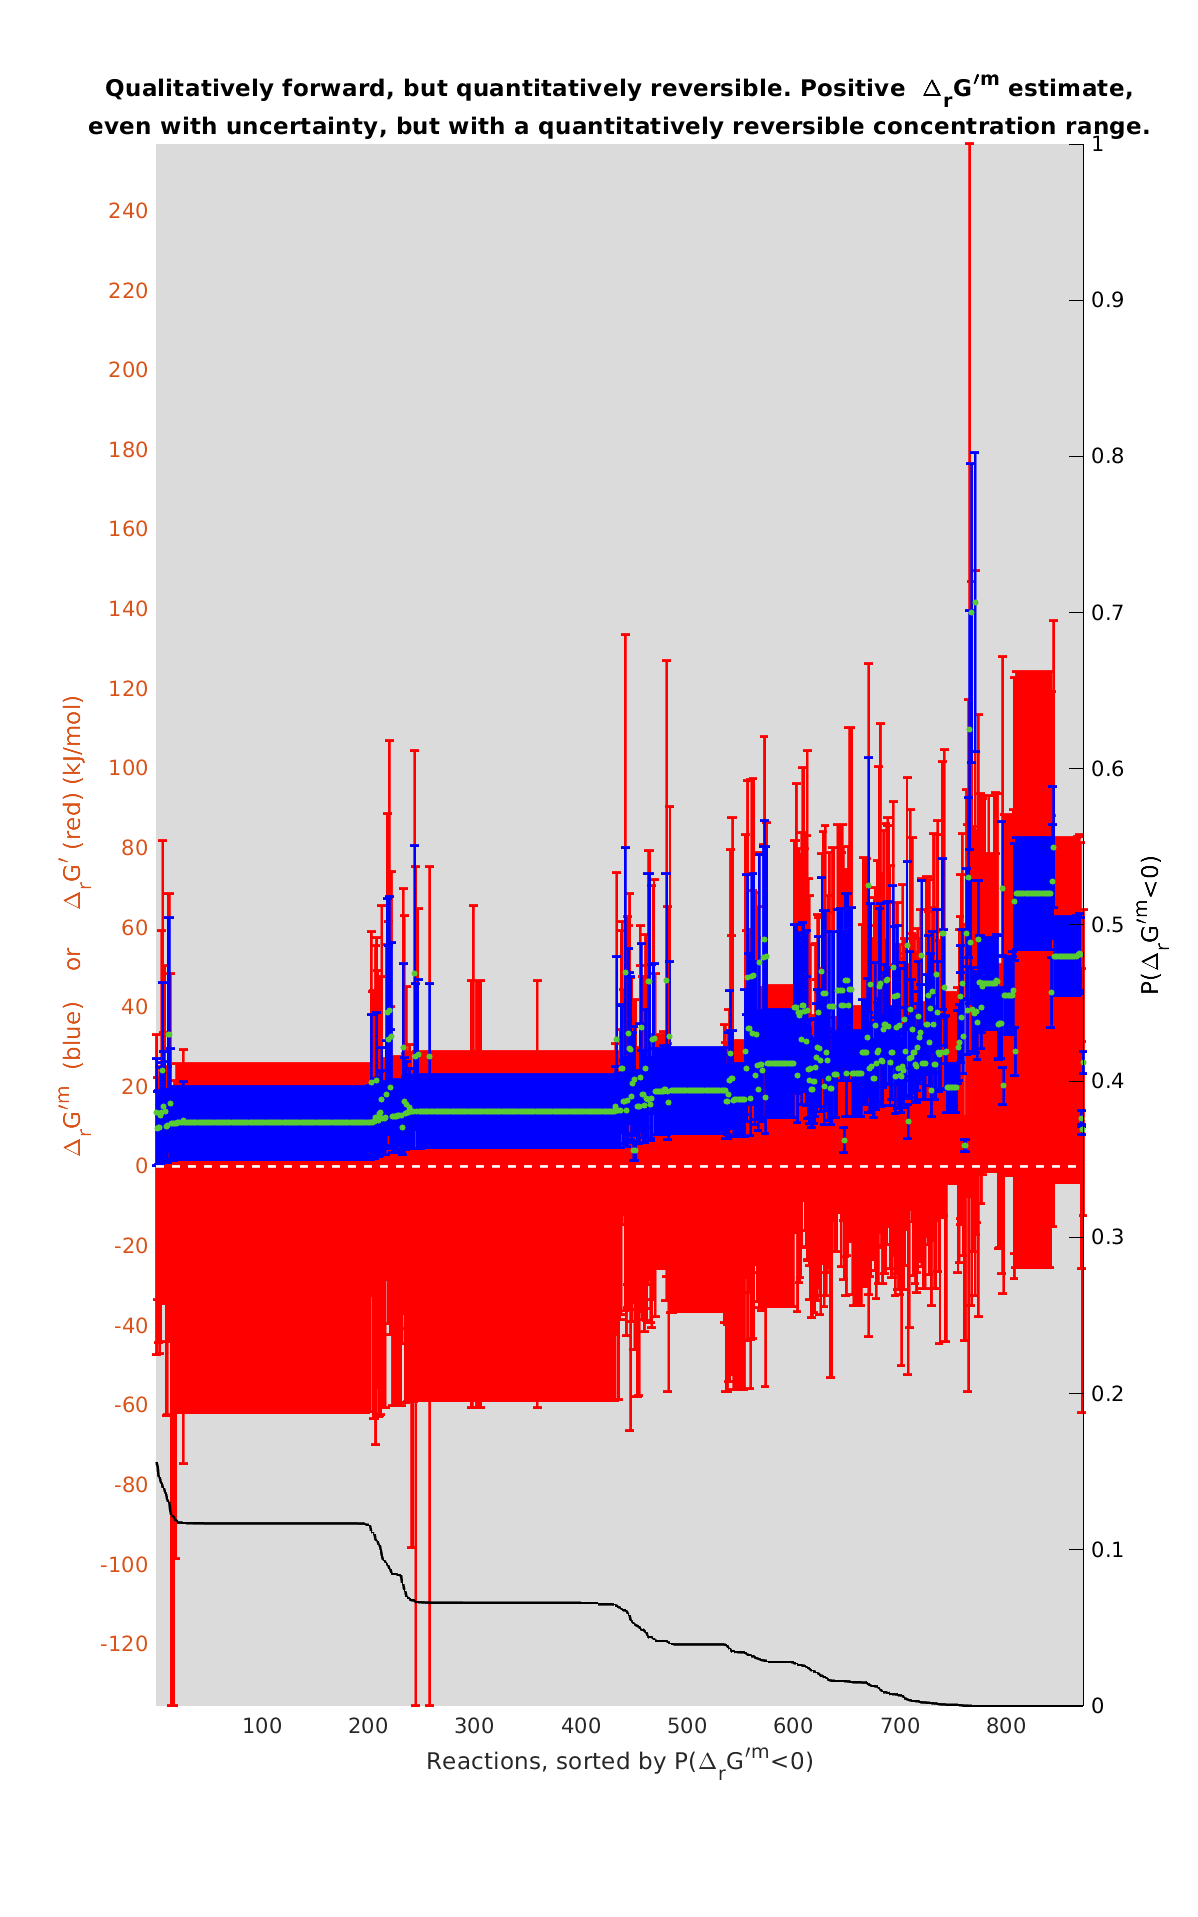

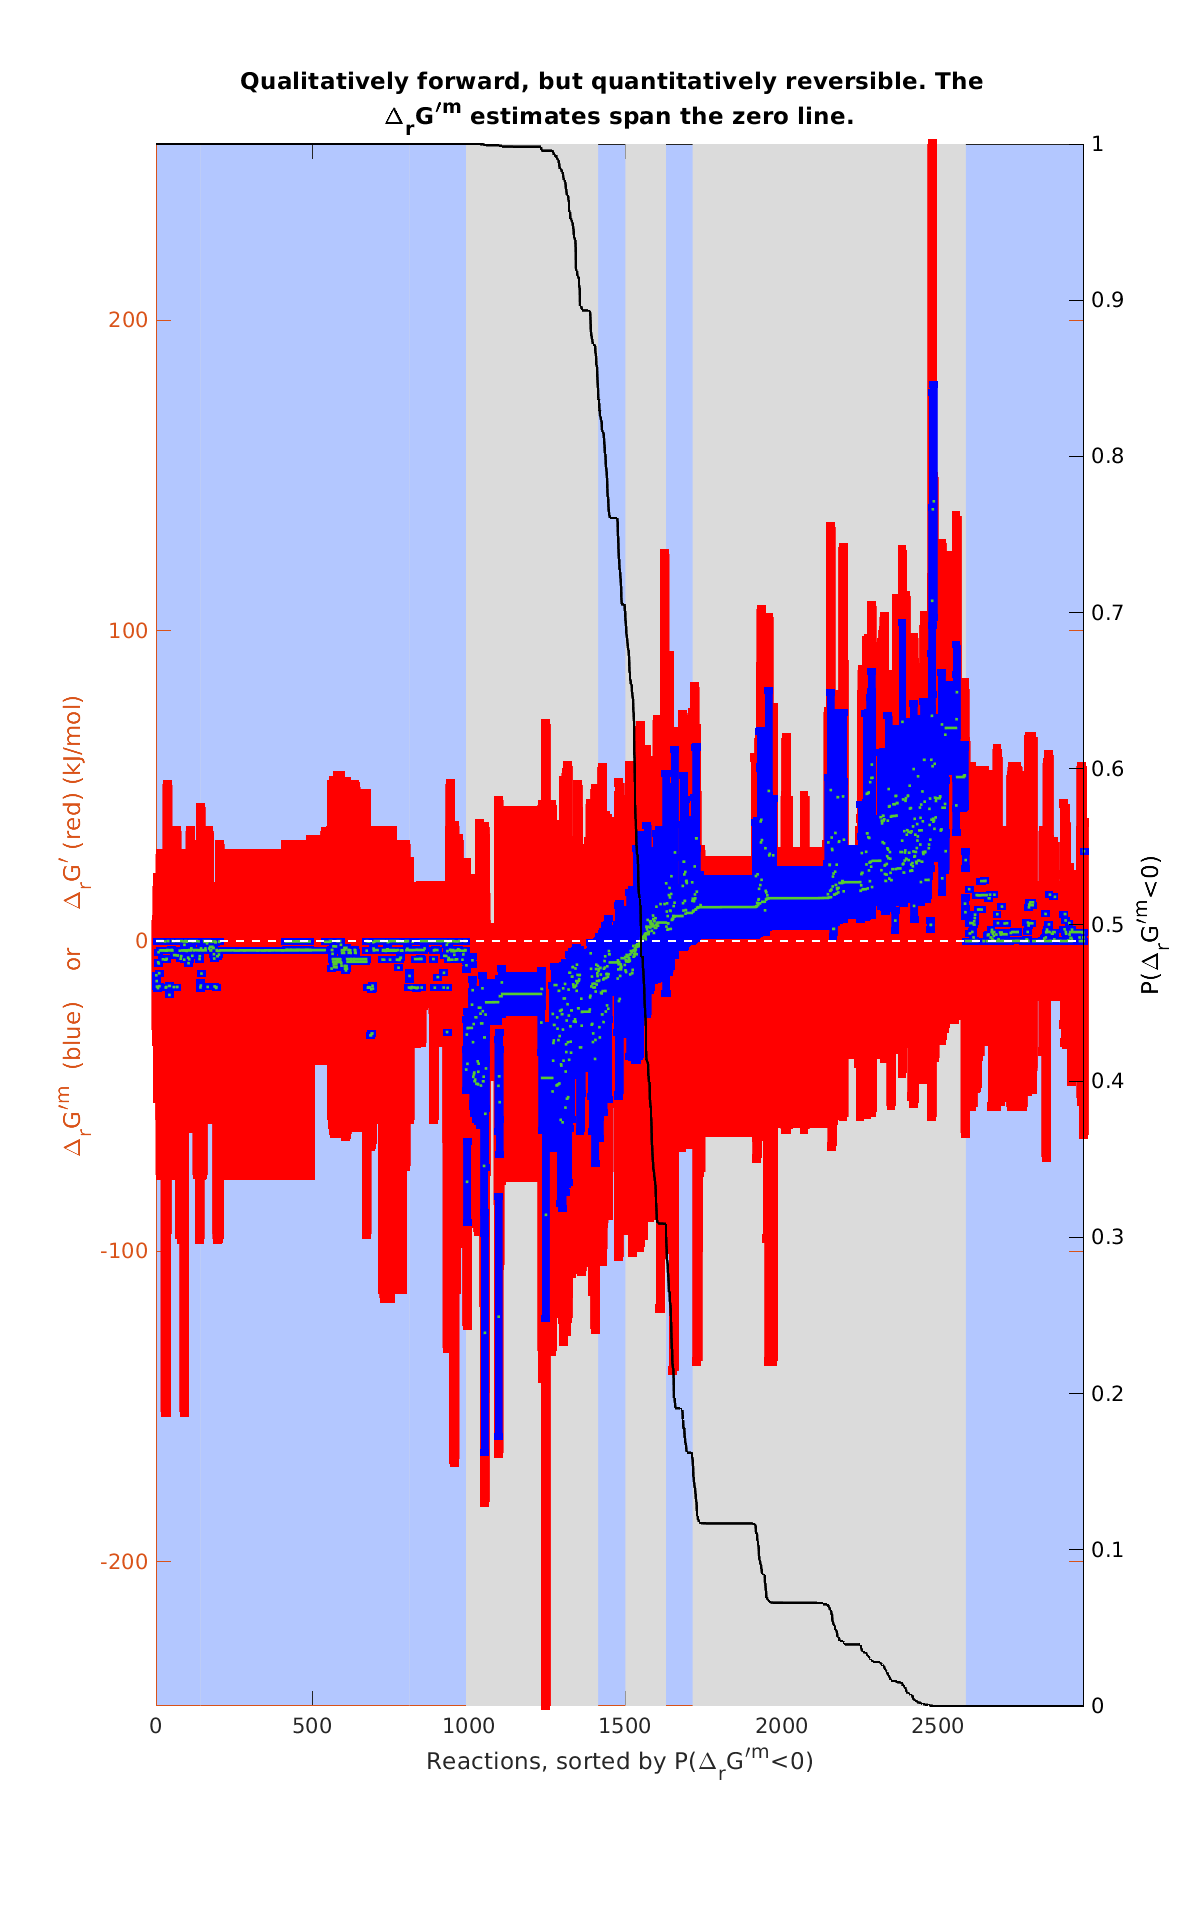

if any(directions.forward2Reversible)
    fprintf('%s\n','forwardReversibleFigures...');
    forwardReversibleFigures(modelThermo,directions,confidenceLevel)
end

Write out tables of experimental and estimated thermochemical parameters for the model

generateThermodynamicTables(modelThermo,resultsBaseFileName);

**REFERENCES**

[1] Fleming, R. M. T. & Thiele, I. von Bertalanffy 1.0: a COBRA toolbox extension to thermodynamically constrain metabolic models. Bioinformatics 27, 142–143 (2011).

[2] Haraldsdóttir, H. S., Thiele, I. & Fleming, R. M. T. Quantitative assignment of reaction directionality in a multicompartmental human metabolic reconstruction. Biophysical Journal 102, 1703–1711 (2012).

[3] Noor, E., Haraldsdóttir, H. S., Milo, R. & Fleming, R. M. T. Consistent Estimation of Gibbs Energy Using Component Contributions. PLoS Comput Biol 9, e1003098 (2013).

[4] Fleming, R. M. T. , Predicat, G.,  Haraldsdóttir, H. S., Thiele, I. von Bertalanffy 2.0 (in preparation).